clc;
clear all;
fid=fopen('D:\NUS\machine vision\chromo.txt');

fid = 3

lf=char(10);
cr=char(13);

A=fscanf(fid,[cr lf '%c'],[64,64]);
fclose(fid);

A=A';
A(isletter(A))=A(isletter(A))-55;
A(A>='0'&A<='9')=A(A>='0'&A<='9')-48;
A=uint8(A);
X=A;

1.display

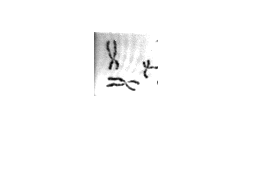

imshow(X,[0,31]);

2.threshold

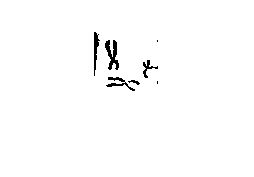


A(A<21)=0;
A(A>=21)=1;
imshow(A,[0,1]);

3.one-pixel thin image

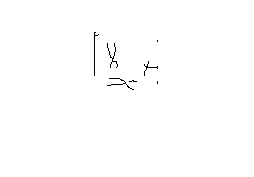

P=A;
se_search=1;%south-east search
cut = zeros(size(A)); %to be cut
cut = uint8(cut);%white
delete_flag=1;
eightnb=zeros(8);
eightnb = uint8(eightnb);%white
while delete_flag
    delete_flag=0;
  for i=2:size(P,1)-1
      for j=2:size(P,2)-1
          if(P(i,j)==1)%white is background
              continue;
          end
          eightnb=[P(i-1,j),P(i-1,j+1),P(i,j+1),P(i+1,j+1),P(i+1,j),P(i+1,j-1),P(i,j-1),P(i-1,j-1)];
          pairnum=0;
          %determine [0,1] pairs
          for k=1:8           
              if(eightnb(k)==0 && eightnb(mod(k,8)+1)==1)%avoid offset
                  pairnum=pairnum+1;
              end
          end
              %south-east search
              if(se_search==1 && sum(eightnb(:))<=6 && sum(eightnb(:))>=2 && pairnum==1)
                  if(eightnb(1)+eightnb(3)+eightnb(5)>0 && eightnb(3)+eightnb(5)+eightnb(7)>0)
                      cut(i,j)=1;%delete i,j (set to white)
                      delete_flag=1;
                  end
              end
              %north-west search
              if(se_search==0 && sum(eightnb(:))<=6 && sum(eightnb(:))>=2 && pairnum==1)
                  if(eightnb(1)+eightnb(5)+eightnb(7)>0 && eightnb(1)+eightnb(3)+eightnb(7)>0)
                      cut(i,j)=1;%delete i,j (set to white)
                      delete_flag=1;
                  end
              end
          
      end
  end
  if(delete_flag==1)%delete some pixels
      P=P+cut;
      cut(:)=0;
      se_search=~se_search;
  end
end
imshow(P,[0,1]);

4.outline

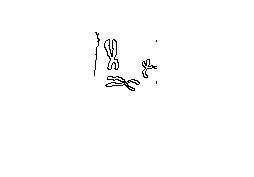

O=ones(size(A));
O=uint8(O);
G1=zeros(size(A));
G1=uint8(G1);
G2=zeros(size(A));
G2=uint8(G2);
for i=1:63
    for j=1:63
        if(A(i,j)==~A(i,j+1))
            G1(i,j)=1;
        end
        if(A(i,j)==~A(i+1,j))
            G2(i,j)=1;
        end
        if(G1(i,j)||G2(i,j)==1)
            O(i,j)=0;
        end
    end
end
imshow(O,[0,1]);

5.label the different objects (8-neighborhood)

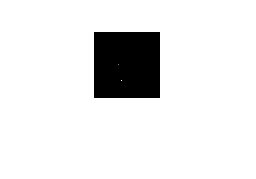

L= zeros(size(X));
L= uint8(L);
Ap = padarray(X,[1 1],1);%1 is background, 0 is object
L = padarray(L,[1 1],0);
isSearched=zeros(size(L));
Lnb = 0;
label=0;
queue=[];
%  1,1  0,-1 1,-1
% -1,0       1,0
% -1,1  0,1  1,1
direction=[-1,0;-1,1;0,1;1,1;1,0;1,-1;0,-1;-1,-1];
for i=2:size(Ap,1)-1
    for j=2:size(Ap,2)-1
        if(Ap(i,j)==1)%is background
            continue;
        end
        if(Ap(i,j)==0 && L(i,j)==0)%is object and not searched
            label=label+1;
            L(i,j)=label;
            queue=[i;j];
            %%%%%%%%%%%%%%%BFS%%%%%%%%%%%%%%%%
            while size(queue)~=0
                center=[queue(1,1),queue(2,1)];
                queue(:,1)=[];%delete this center from queue
                for k = 1:8 
                    sround=center+direction(k,:);%sround is 1x2 matrix (i,j)
                    if(Ap(sround(1),sround(2))==0 && L(sround(1),sround(2))==0)%is objective and not searched
                        L(sround(1),sround(2))=label;%label this sround
                        queue = [queue,[sround(1);sround(2)]];%(sround1,sround2) as center
                    end
                end
            end
        end
    end
end
imshow(L,[0,label]);

6.rotate the original image by 30 degree, 60 degrees and 90 degrees

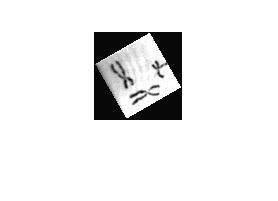

angle=30;
w=size(A,2);
h=size(A,1);
R=X;
rotate=[cosd(angle) -sind(angle);sind(angle) cosd(angle)];
rotate=rotate';%inverse rotate

TargetH = ceil(w*sind(angle) + h*cosd(angle)) ; %rotate height
TargetW = ceil(w*sind(angle) + h*cosd(angle)) ; %rotate width

TargetPicture=ones(TargetH,TargetW);
centerOPot=[0.5*h,0.5*w];%original center
centerPot=[0.5*TargetH,0.5*TargetW];%new center
for i=1:TargetW
    for j=1:TargetH
        currPoint=[i;j];%2x1
        Op=rotate*(currPoint-centerPot)+centerOPot;
        mn=floor(Op);
        ab=Op-mn;%ab=(a,b) a:wdistance b:hdistance
        a=ab(1);
        b=ab(2);
        m=mn(1);
        n=mn(2);
       if(Op(1)>=1 && Op(1)<h && Op(2)>=1 && Op(2)<w)
           TargetPicture(i,j)=(1-a)*(1-b)*R(m,n)+a*(1-b)*R(m+1,n)+(1-a)*b*R(m,n+1)+a*b*R(m+1,n+1);
       end
    end
end
imshow(TargetPicture,[0,31]);